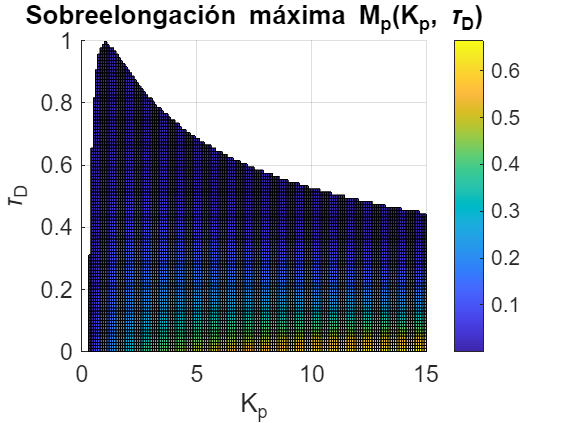

% Limpiar entorno
close all;
clear;
clc;

% Parámetros constantes
K = 1;
p = 1;
nu = 0.1;

[Kp, tauD] = meshgrid(linspace(0.3,15,150), linspace(0,1.5,150));
A  = p + Kp.*K.*tauD;
B  = sqrt(4*K.*Kp - A.^2);

valid = B>0 & (A./(2*sqrt(K.*Kp)))<=1;

Mp  = nan(size(Kp));
tp  = nan(size(Kp));
tr  = nan(size(Kp));
ts  = nan(size(Kp));

Mp(valid) = exp(-pi * A(valid) ./ B(valid));

% 1) Tiempo al pico: t_p = (A*pi)/(B*p)
tp(valid) = (A(valid)*pi) ./ (B(valid)*p);

phi = acos( p./(2*sqrt(K.*Kp(valid))) );

% 2) Tiempo de subida: t_r = A*(pi-phi)/(B*p)
tr(valid) = A(valid) .* (pi - phi) ./ (B(valid)*p);

% 3) Tiempo de establecimiento: t_s = (1/p)*log(2*sqrt(K*Kp)/(nu*B))
ts(valid) = (1/p) * log( (2*sqrt(K.*Kp(valid))) ./ (nu * B(valid)) );

% Gráficas
figure;
surf(Kp, tauD, Mp);
view(2);             % Vista superior
xlabel('K_p'); ylabel('\tau_D'); zlabel('M_p');
title('Sobreelongación máxima M_p(K_p, \tau_D)');
set(gca, 'FontSize', 13); colorbar;

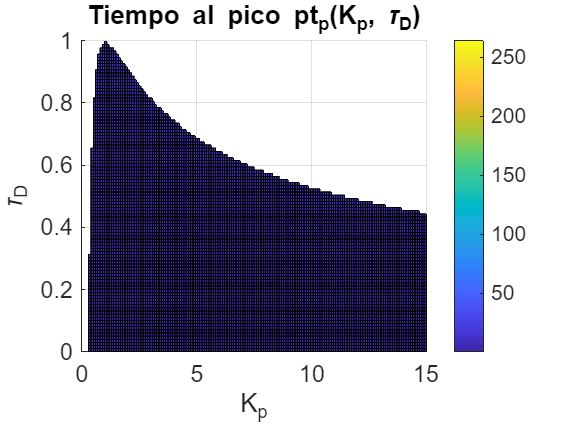


figure;
surf(Kp, tauD, tp);
view(2);
xlabel('K_p'); ylabel('\tau_D'); zlabel('pt_p');
title('Tiempo al pico pt_p(K_p, \tau_D)');
set(gca, 'FontSize', 13); colorbar;

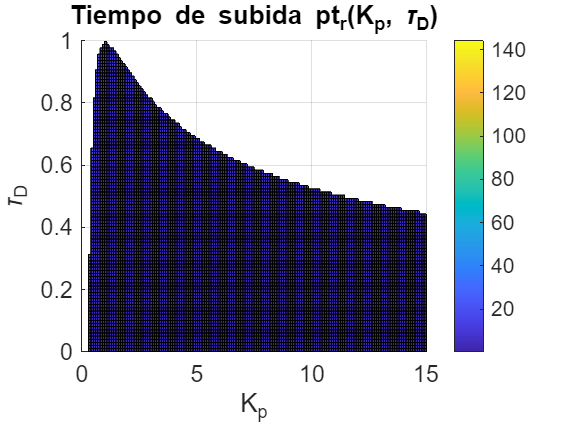


figure;
surf(Kp, tauD, tr);
view(2); 
xlabel('K_p'); ylabel('\tau_D'); zlabel('pt_r');
title('Tiempo de subida pt_r(K_p, \tau_D)');
set(gca, 'FontSize', 13); colorbar;

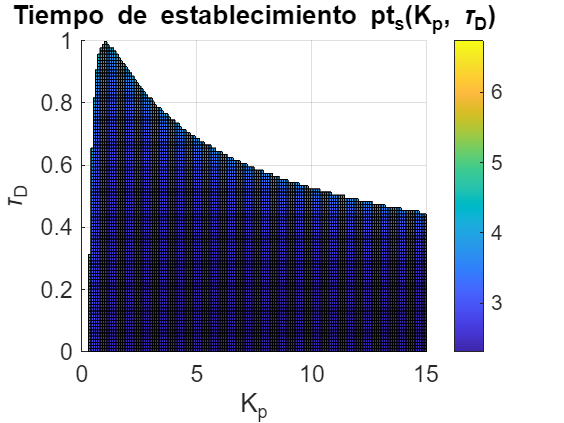


figure;
surf(Kp, tauD, ts);
view(2); 
xlabel('K_p'); ylabel('\tau_D'); zlabel('pt_s');
title('Tiempo de establecimiento pt_s(K_p, \tau_D)');
set(gca, 'FontSize', 13); colorbar;

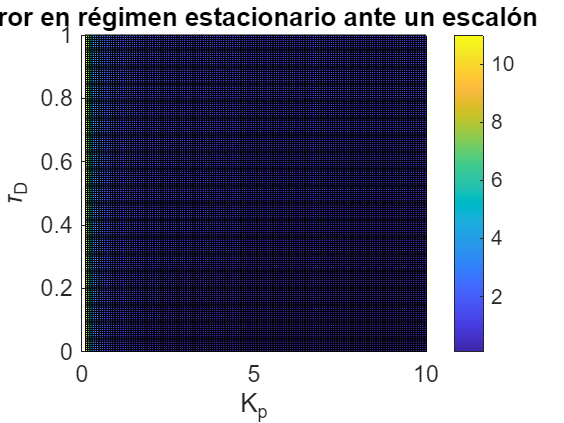

clear;
clc;

% Parámetros constantes
K = 1;
p = 1;

% Rango de Kp y tauD
[Kp, tauD] = meshgrid(linspace(0.1, 10, 150), linspace(0, 1, 150));

% Cálculo del error en régimen estacionario
e_inf = (p + Kp .* K .* tauD) ./ (Kp * K);

% Graficar superficie
figure;
surf(Kp, tauD, e_inf);
view(2); 
xlabel('K_p', 'FontSize', 13);
ylabel('\tau_D', 'FontSize', 13);
zlabel('e_{P-D,1}(\infty)', 'FontSize', 13);
title('Error en régimen estacionario ante un escalón', 'FontSize', 13);
set(gca, 'FontSize', 13);
colorbar;

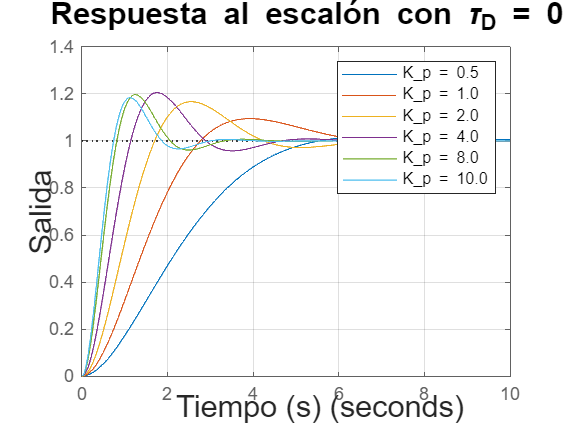

close all;
clear;
clc;

% Parámetros del sistema
K = 1;
p = 1;
t = 0:0.01:10;

%% Gráfica 1: tau_D fijo, Kp variable
tauD_fixed = 0.2;
Kp_vals = [0.5, 1, 2, 4, 8, 10];

fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);  % Tamaño físico
hold on;
for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    num = Kp * K;
    den = [1, (p + Kp * K * tauD_fixed), Kp * K];
    sys = tf(num, den);
    step(sys, t);
end
title(['Respuesta al escalón con \tau_D = ' num2str(tauD_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(k) sprintf('K_p = %.1f', k), Kp_vals, 'UniformOutput', false));
grid on;
% set(gca, 'FontSize', 13);
print(fig1, 'salidaKpconst', '-dpdf', '-r300');  % o usa exportgraphics

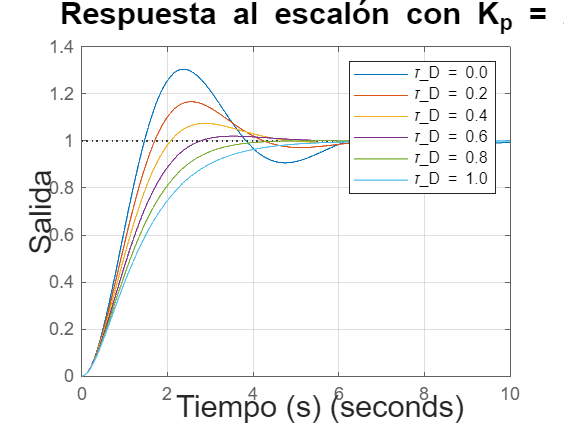



%% Gráfica 2: Kp fijo, tau_D variable
Kp_fixed = 2;
tauD_vals = [0, 0.2, 0.4, 0.6, 0.8, 1.0];

fig2 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(tauD_vals)
    tauD = tauD_vals(i);
    num = Kp_fixed * K;
    den = [1, (p + Kp_fixed * K * tauD), Kp_fixed * K];
    sys = tf(num, den);
    step(sys, t);
end
title(['Respuesta al escalón con K_p = ' num2str(Kp_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(t) sprintf('\\tau_D = %.1f', t), tauD_vals, 'UniformOutput', false));
grid on;

% Evita DIN A4 y recorte
set(fig2, 'PaperUnits', 'centimeters');
set(fig2, 'PaperSize', [20 15]);
set(fig2, 'PaperPosition', [0 0 20 15]);

print(fig2, 'salidataucnst', '-dpdf', '-r300');